# Advanced control for autonomous vehicles

## Assignment 1

Draw a representation of the following vector field:


$$f\left(X\left(t\right)\right)=\left\lbrack \begin{array}{c}
-\frac{6x}{{\left(1+x^2 \right)}^2 }+2y\\
-\frac{2x+2y}{{\left(1+x^2 \right)}^2 }
\end{array}\right\rbrack \;\mathrm{with}\;X\left(t\right)={\left(x,y\right)}^t$$


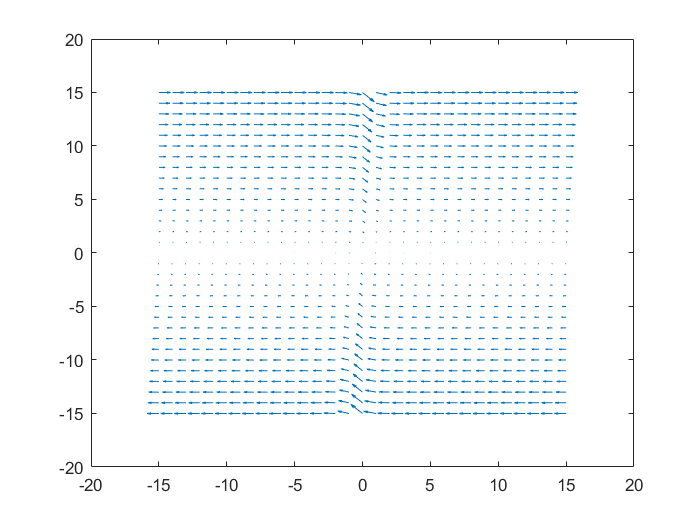

x_start = -15;
y_start = -15;
x_end = 15;
y_end = 15;

[YY, XX] = meshgrid(x_start:x_end,y_start:y_end);


U = zeros(abs(x_start-x_end)+1,abs(y_start-y_end)+1);
V = zeros(abs(x_start-x_end)+1,abs(y_start-y_end)+1);

%keyboard

i=0;
j=0;


for x = x_start:x_end
    
    i=i+1;
    j=0;
    
    for y = y_start:y_end
        
        j=j+1;
        
        u = - (6 * x)/((1+x^2)^2)+2*y;
        v = - (2*x+2*y)/((1+x^2)^2);
        
        %keyboard
        
        U(i,j) = u;
        V(i,j) = v;
        
    end
end

figure(1)
%pcolor(XX,YY,U)
quiver(XX,YY,U,V)

The vector field is determined over an area of points (x,y). We need to go through all these points, (therefore the 2 for loops) then calculate the value of f(X(t)) at each point. To use quiver, we need equivalently sized matrices, so that's why we have U and V for both parameters of f(X(t)). The sizes of U and V are dependent on the number of points and we need to not forget to add +1 to the size since it is Matlab (can't call a 0 in the matrices).

## Assignment 2

Draw a representation of the following vector field (Lotka-Volterra):


$$f\left(X\left(t\right)\right)=\left\lbrack \begin{array}{c}
x\left(1-y\right)\\
y\left(x-1\right)
\end{array}\right\rbrack \;\mathrm{with}\;X\left(t\right)={\left(x,y\right)}^t$$


We will use a method similar to the previous exercise.

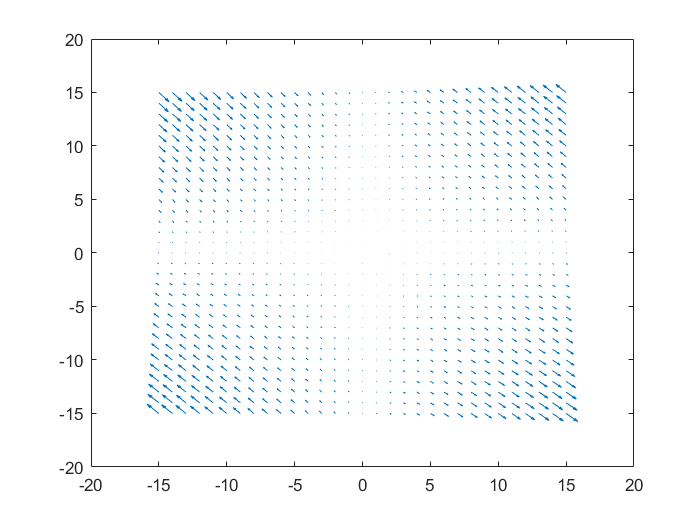

x_start = -15;
y_start = -15;
x_end = 15;
y_end = 15;

[YY, XX] = meshgrid(x_start:x_end,y_start:y_end);

U = zeros(abs(x_start-x_end)+1,abs(y_start-y_end)+1);
V = zeros(abs(x_start-x_end)+1,abs(y_start-y_end)+1);

i=0;
j=0;

for x = x_start:x_end
    
    i=i+1;
    j=0;
    
    for y = y_start:y_end
        
        j=j+1;
        
        u = x*(1-y);
        v = y*(x-1);
        
        U(i,j) = u;
        V(i,j) = v;
        
    end
end

figure(2)
quiver(XX,YY,U,V)

## Assignment 3

Try replacing the x(t) in the equation ? And test multiple c?

## Assignment 4

Pick a point and simulate its trajectory with Assignment 1 vector field.

%First recreate the vector field

x_start = -15;
y_start = -15;
x_end = 15;
y_end = 15;

[YY, XX] = meshgrid(x_start:x_end,y_start:y_end);

U = zeros(abs(x_start-x_end)+1,abs(y_start-y_end)+1);
V = zeros(abs(x_start-x_end)+1,abs(y_start-y_end)+1);

i=0;
j=0;

for x = x_start:x_end
    
    i=i+1;
    j=0;
    
    for y = y_start:y_end
        
        j=j+1;
        
        u = - (6 * x)/((1+x^2)^2)+2*y;
        v = - (2*x+2*y)/((1+x^2)^2);
        
        U(i,j) = u;
        V(i,j) = v;
        
    end
end

%Then pick a point and calculate its trajectory
x_point = zeros(240,1);
y_point = zeros(240,1);
x_point(1) = -10;
y_point(1) = 10;


for iteration = 1:239
    
    m = interp2(x_start:x_end,y_start:y_end, U(iteration+1)', x(iteration), y(iteration));
    n = interp2(x_start:x_end,y_start:y_end, vx(:,:,iteration+1)', x(iteration), y(iteration));

    x(iteration+1) = x(iteration) + m;
    y(iteration+1) = y(iteration) + n;
end

Error using griddedInterpolant
Interpolation requires at least two sample points for each grid dimension.

Error in interp2>makegriddedinterp (line 228)
    F = griddedInterpolant(varargin{:});

Error in interp2 (line 128)
        F = makegriddedinterp({X, Y},


figure(1)
quiver(XX,YY,U,V)